# ROZWIĄZYWANIE RÓWNAŃ NIELINIOWYCH

## PARAMETRY LOKALNEJ ZBIEŻNOŚCI

Teraz zajmijmy się drugim istotnym parametrem zbieżności - wykładnikiem zbieżności $\varrho$. 


$$\Delta_{i+1} =C\Delta_i^{\rho }$$


Rozwiążemy nasz problem za pomocą dwóch modyfikacji metody Newtona: samą metodą Newtona i metodą *regula falsi*.

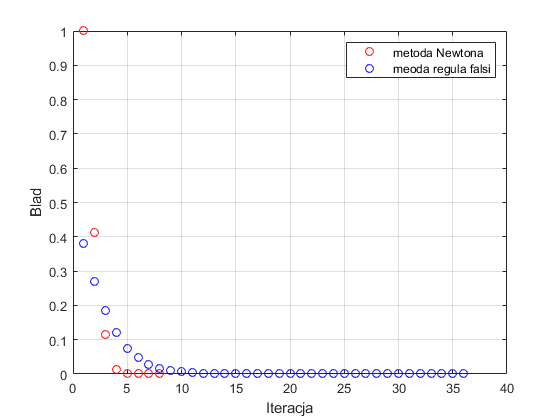

% Do rozwiązania przyjmiemy prostą funkcję o oczywistym rozwiązaniu
% teoretycznym
f = @(x) (x-1).*(x-2).*(x-5);
df = @(x) (x - 1).*(x - 2) + (x - 1).*(x - 5) + (x - 2).*(x - 5);
true_root = 1;
% Pierwszy testy wykonamy dla metody bisekcji
options.imax = 100;    %w ten sposób ustawiamy maksymalna ilość iteracji
options.return_all = true;  % ta flaga powoduje zwrócenie wyników pośrednich w kolejnych iteracjach
options.TOL = 1e-8; % zakładana dokładność
options.warnings = true; % dostaniemy warning w przypadku jakby coś poszło nie tak

% Ustalamy włąściewe warunki startowe dla metody Newtona
a = 0;
b = 1.5;
x0 = -1;
% Uruchamiamy implementację metody Newtona
[resultsNewton] = calculateNewtonSolution(f,df,x0,options);
errorNewton = abs(resultsNewton - true_root);
plot(errorNewton, 'ro'); xlabel('Iteracja'); ylabel('Blad'); grid on;hold on;

% Powtarzamy procedurę dla metody regula falsi
[resultsFalsePosition] = calculateFalsePositionSolution(f,a,b,options);
errorFalsePosition = abs(resultsFalsePosition - true_root);
plot(errorFalsePosition, 'bo');xlabel('Iteracja'); ylabel('Blad'); grid on;hold off;
legend('metoda Newtona', 'metoda regula falsi');

Te dwie metody różnią się wykładnikiem zbieżności. Zauważ ile iteracji zrobiła metoda Newtona a ile metoda *regula falsi*. Aby lepiej to pokazać wykreślmy błąd rozwiązania w funkcji numeru iteracji w skali półlogarytmicznej:

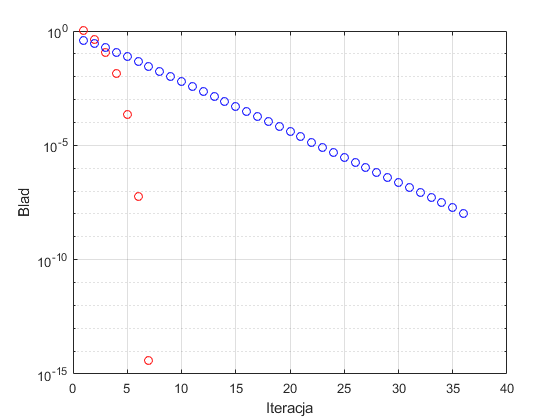

semilogy(errorNewton, 'ro'); xlabel('Iteracja'); ylabel('Blad'); grid on;hold on;
semilogy(errorFalsePosition, 'bo');xlabel('Iteracja'); ylabel('Blad'); grid on;hold off;

Widać wyraźnie, że wykładnik lokalnej zbieżności jest znacznie silniejszy od wpływu współczynnika. Radykalnie zmienia ilośc iteracji potrzebnych do osiągnięcia rozwiązania. Jest to jednak okupione najczęściej zmniejszeniem zakresu w jakim dana metoda daje wynik (najczęściej chodzi o zakres punktów startowych, rozwiązań do których może być zbieżna lub funkcji dla których działa)

**ĆWICZENIE 1:**

Spróbuj znaleźć taki zestaw danych wejściowych dla którego metoda Newtona będzie rozbieżna albo będzie wymagała zbliżonej ilości iteracji jak metoda *regula falsi*. Czy potrafisz wyjaśnić dlaczego może się tak zdarzyć mimo, że ma ona większy wykładnik zbieżności?

Podpowiedź: Kluczowe jest tutaj położenie punktu startowego

Efekt który obserwowaliśmy powyżej może zostać doprowadzony do przypadku skrajnego. Przykładowo w poniższym kodzie:

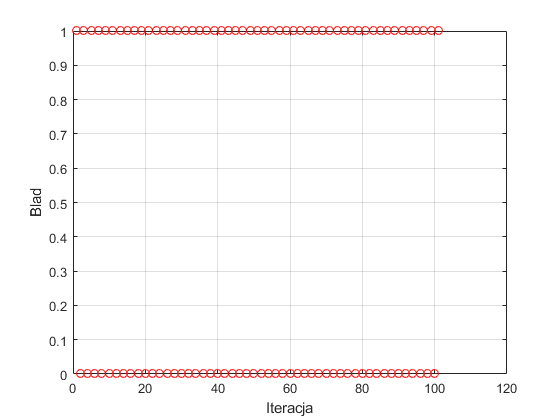

% Przyjmijmy inny wielomian jako przykład
f = @(x)x.^3-2.*x+2;
df = @(x) 3.*x.^2-2;

% Ograniczmy ilośc iteracji - PAMIĘTAJ ŻEBY ZAWSZE OGRANICZAĆ ILOŚĆ
% ITERACJI
options.imax = 100;    %w ten sposób ustawiamy maksymalna ilość iteracji
options.return_all = true;  % ta flaga powoduje zwrócenie wyników pośrednich w kolejnych iteracjach
options.TOL = 1e-8; % zakładana dokładność
options.warnings = true; % dostaniemy warning w przypadku jakby coś poszło nie tak

% Uruchamiamy implementację metody Newtona
x0 = 1;
true_root2 = -1.7692923542386; % rzeczywisty pierwiastek wielomianu x^3-2x+2
[resultsNewton] = calculateNewtonSolution(f,df,x0,options);
errorNewton = abs(resultsNewton - true_root2);

plot(errorNewton, 'ro'); xlabel('Iteracja'); ylabel('Blad'); grid on;hold off;
 

To klasyczny przykład cyklu. Zwróć uwagę, że to czy metoda wpadnie w cykl zależy od położenia punktu startowego.

**ĆWICZENIE 2:**

Zmodyfikuj powyższy kod tak, aby metoda stała się zbieżna.

**ĆWICZENIE 3:**

Korzystając z definicji parametrów zbieżności:


$$\Delta_{i+1} =C\Delta_i^{\rho }$$


Zmodyfikuj poniższy kod tak, żeby pokazać kwadratową zależność błędu w metodzie Newtona ($\left.\varrho =2\right)$

% Przyjmijmy inny wielomian jako przykład
f = @(x)x.^3-2.*x+2;
df = @(x) 3.*x.^2-2;

% Ograniczmy ilośc iteracji - PAMIĘTAJ ŻEBY ZAWSZE OGRANICZAĆ ILOŚĆ
% ITERACJI
options.imax = 100;    %w ten sposób ustawiamy maksymalną ilość iteracji
options.return_all = true;  % ta flaga powoduje zwrócenie wyników pośrednich w kolejnych iteracjach
options.TOL = 1e-8; % zakładana dokładność
options.warnings = true; % dostaniemy warning w przypadku jakby coś poszło nie tak

% Uruchamiamy implementację metody Newtona
x0 = 1;
[resultsNewton] = calculateNewtonSolution(f,df,x0,options);

% Swój kod umieść poniżej


 